# Feasibility of Deep Learning to Classify Teat-end Hyperkeratosis

### Preamble

This work was performed by P.S. Basran, I. Porter, and M. Weiland at Cornell University, College of Veterinary Medicine, Dept Clinical Sciences and Population Health. This work is licenced under GNU General Public License Version 3 ([https://www.gnu.org/licenses/gpl-3.0.en.html](https://www.gnu.org/licenses/gpl-3.0.en.html)).

This mlx is largely based on 2 sources: 

- Matlab deep learning MLX using GoogleLet (download the [example here ](https://www.mathworks.com/help/deeplearning/ug/train-deep-learning-network-to-classify-new-images.html)and ensure it is in your path )

- Oversampling for deep learning* 

*Kenta (2020). Oversampling for deep learning: classification example (https://www.mathworks.com/matlabcentral/fileexchange/78020-oversampling-for-deep-learning-classification-example), MATLAB Central File Exchange. Retrieved October 20, 2020.

Please contact psb92 at cornell dot edu for questions and information.

#### How to use this script:

- Load the data. Create the datasets of individual teat images cropped as shown. The dimensions do not matter so long as they are (roughly) square. All images will be downsampled to the dimensions needed for the deep learning. Images of similar class must be placed in a folder, referenced in this script as 'Score1', 'Score2' etc., Raw images displaying all teats can be classified / labelled using a Matlab GUI described here: [https://www.sciencedirect.com/science/article/pii/S0022030220306457,](https://www.sciencedirect.com/science/article/pii/S0022030220306457,) and this matlab GUI is also located in this repository. It requires a bit of tinkering to fit local needs, so please contact psb92 at cornell dot edu if you wish to use it to help digitally classify your teats.The path needs to be set to the location of where this script is and the location of the folder containing the (sub) folders of teat end images. In the Load data section, you can specify the % of training, validation and testing data (fraction of 1.0).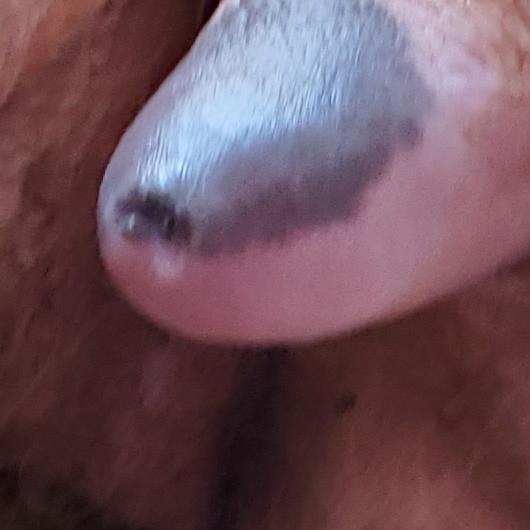

- Choose a network for deep learning. In this publication, we chose to use GoogleNet. In order for this to work GoogleNet needs to be downloaded on your system and accessible by Matlab. You will need to ensure that the path has been set to access this folder as it calls a function 'findLayersToReplace.m'.

- We assume the dataset is imbalanced and thus we will use the balancing method described by Kenta (see reference above).

- Load the pre-trained network (GoogleNet is the default here). Note the "Freeze Layers" is hard coded based on the size of the net used (10 for GoogleNet).

- Specify data augmentation settings pixelRange, RotationRange, and scaleRage. 

- Specify training options. These parameters can be adjusted / experimented with.

- Train the network!

- Assess the classification. This section will generate AUC curves and accuracy assessments. Based on your findings from a run, you can adjust your training options, adjust the network, etc., until you are achieving a result which you can test.

- FINAL TESTING. DO ONLY ONCE! The idea is to do this only once with your dataset (Better, leave the test dataset completely out of this script and test it independently). Thus this part of the code is commented out until you are prepared to 'test' your model.

## 1. Load data

Here we clean up our workspace, figures and set our image directory paths

Please download Food image dataset provided from MathWorks. The Example Food Images data set contains 978 photographs of food in nine classes (*ceaser_salad*, *caprese_salad*, *french_fries*, *greek_salad*, *hamburger*, *hot_dog*, *pizza*, *sashimi*, and *sushi*).

Other dataset is available at [https://jp.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html.](https://jp.mathworks.com/help/deeplearning/ug/data-sets-for-deep-learning.html.) 

clearvars;clc;close all

cd('/Users/psb92/Sync/_current/Teat/ImageSet_MW/');     % Location of where this script is
loc = '/Users/psb92/Sync/_current/Teat/ImageSet_MW/';   % "Upper" folder containing subfolders 'Score1', 'Score2', etc., 
%addpath ='/Users/psb92/Documents/MATLAB/Examples/R2020a/nnet/TransferLearningUsingGoogLeNetExample';


imds = imageDatastore(loc, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames', ...
    'FileExtensions','.jpg'); 

TrainPercent = 0.70;            % Specify % of this dataset you want to use for training
ValidatePercent = 0.15;         % Specify % of this dataset you want to use for validation
TestPercent = 0.15;             % Specify % of this dataset you want to use for testing... AGAIN! DO NOT RUN as per 9.

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,TrainPercent,ValidatePercent,TestPercent);

## 2. Load Pretrained Network

Load a pretrained GoogLeNet network. If the Deep Learning Toolbox™ Model *for GoogLeNet Network*. Dropdown allows for other pretrained networks assuming the package is downloaded/available. 

Currently, Resnet50 and GoogLeNet have been explored but GoogLeNet seems to fair a bit better.

net = googlenet;

## 3. Balance dataset and over sample correction

 See [https://www.mathworks.com/matlabcentral/fileexchange/78020-oversampling-for-deep-learning-classification-example](https://www.mathworks.com/matlabcentral/fileexchange/78020-oversampling-for-deep-learning-classification-example).

Extract label information in training dataset

labels=imdsTrain.Labels;

Use findgroups function to obtain group index which corresponds to each class. For example, you have the category of dog, cat, and sheep. The index of 1, 2 and 3 was assigned to dog, cat and sheep, respectively. Namely, if you have 5 training images of dog, dog, cat, sheep and dog, the index will be [1 1 2 3 1], corresponding to variable G.  

[G,classes] = findgroups(labels);

The splitandapply finction apply a certain function to each class. The code below uses numel function to count the dimension of the variable labels at each class. The size of labels and G is identical so that the group index at each label in the variable label can be easily confirmed.  

numObservations = splitapply(@numel,labels,G);

Calculate the number of images comprising the majority class. 

desiredNumObservationsPerClass = max(numObservations);

Use splitandapply function again. The function to use is randReplicateFiles function which is placed at the end of this script. It returns a random integer and the number of integer to sample is defined by the variable desiredNumObservationsPerClass. desiredNumObservationsPerClass corresponds to the number of images included in most frequent class. 

files = splitapply(@(x){randReplicateFiles(x,desiredNumObservationsPerClass)},imdsTrain.Files,G);
files = vertcat(files{:});

Collect label data. The label name is between ￥ and ￥. Search the location of second-to-last and last ￥. 

labels=[];info=strfind(files,'/');
for i=1:numel(files)
    idx=info{i};
    dirName=files{i};
    targetStr=dirName(idx(end-1)+1:idx(end)-1);
    targetStr2=cellstr(targetStr);
    labels=[labels;categorical(targetStr2)];
end
imdsTrain.Files = files;
imdsTrain.Labels=labels;
labelCount_oversampled = countEachLabel(imdsTrain)

labelCount_oversampled = 4×2 table
     Label     Count
    _______    _____

    Score 1     458 
    Score 2     458 
    Score 3     458 
    Score 4     458 


## 4. Load the pre-trained model,

net.Layers(1);
inputSize = net.Layers(1).InputSize;
if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 
[learnableLayer,classLayer] = findLayersToReplace(lgraph);

We have used these weights / learn rate factors, but they can be played with.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);
layers = lgraph.Layers;
connections = lgraph.Connections;

FreezeLayers = 10;%length(layers)-1; Densenet... first 6 layers frozen, GoogLeNet =10

layers(1:FreezeLayers) = freezeWeights(layers(1:FreezeLayers));
lgraph = createLgraphUsingConnections(layers,connections);

## 5. Data Augmentation

Augment the data by adjusting the center of the image (pixelRange) in pixels, rotation (RotationRange) in degrees, and scale (scaleRange) which dilates/compresses the image by a scalar factor. We also allow for reflections about the 'x' axis.

pixelRange = [-90 90];
RotationRange = [-30 30];
scaleRange = [0.8 1.2];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange, ...
    'RandRotation',RotationRange ...
    ); 
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
     'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

## 6. Training Options

See Matlab documentation for details on these settings.

miniBatchSize = 64;
valFrequency = max(floor(numel(augimdsTest.Files)/miniBatchSize)*10,1);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',50, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',true, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.8, ...
    'LearnRateDropPeriod',3, ...
    'Plots','training-progress');

## 7. Train  network

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:12 |       25.00% |       37.83% |       3.4044 |       2.6381 |          0.0003 |


|       2 |          30 |       00:02:48 |       48.44% |       49.57% |       1.0568 |       0.9841 |          0.0003 |


|       2 |          50 |       00:04:27 |       67.19% |              |       0.7582 |              |          0.0003 |


|       3 |          60 |       00:05:17 |       71.88% |       61.30% |       0.6689 |       0.7880 |          0.0003 |


|       3 |          64 |       00:05:38 |       70.31% |              |       0.6176 |              |          0.0003 |
|======================================================================================================================|


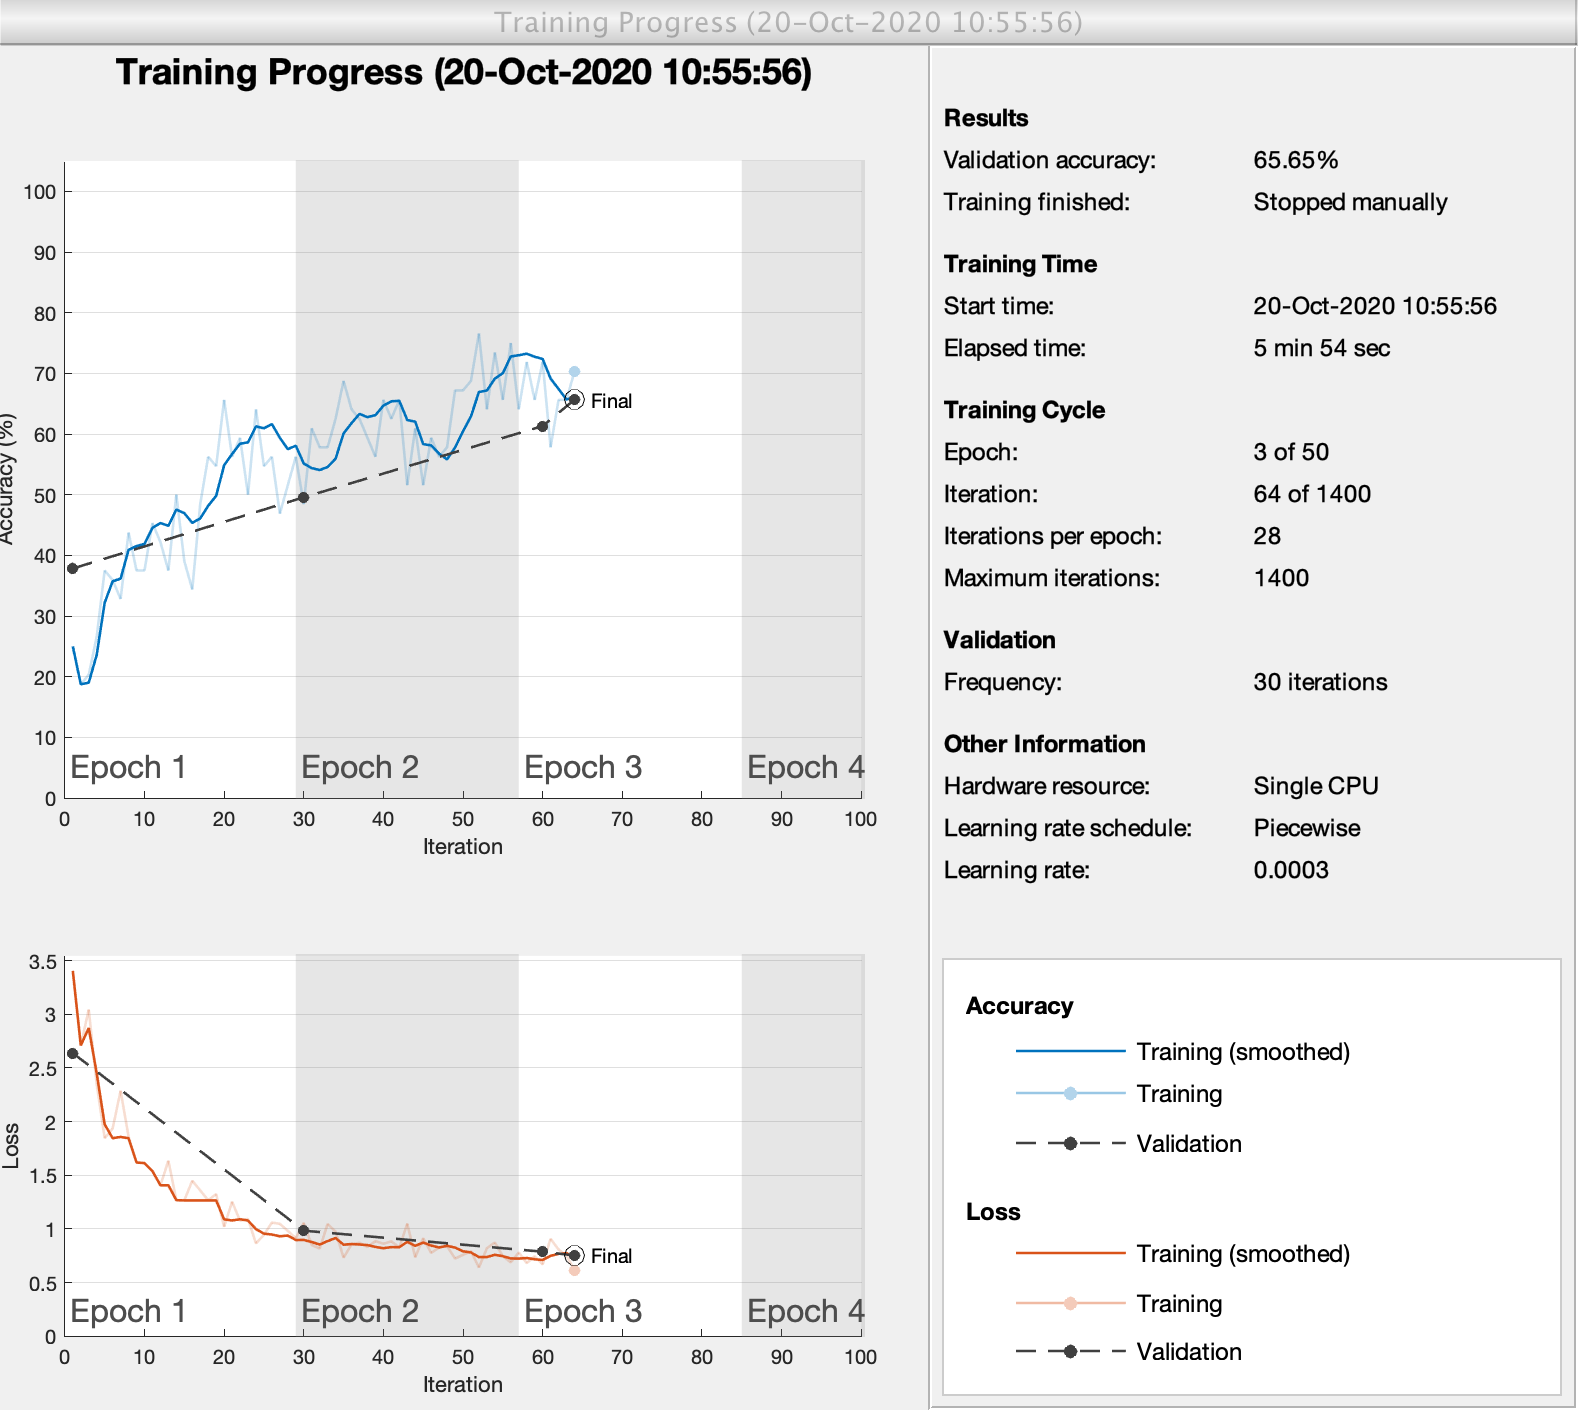

net = trainNetwork(augimdsTrain,lgraph,options);

## 8. Classification assessment 

Here we will produce a number of figures as compute a number things, such as the overall accuracy, confusion matrix, and a display of 16 validation images along with their associated predictions (and percentages).

[YPred,probs] = classify(net,augimdsValidation);
% Accuracy in predictions in the validation dataset
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.6565

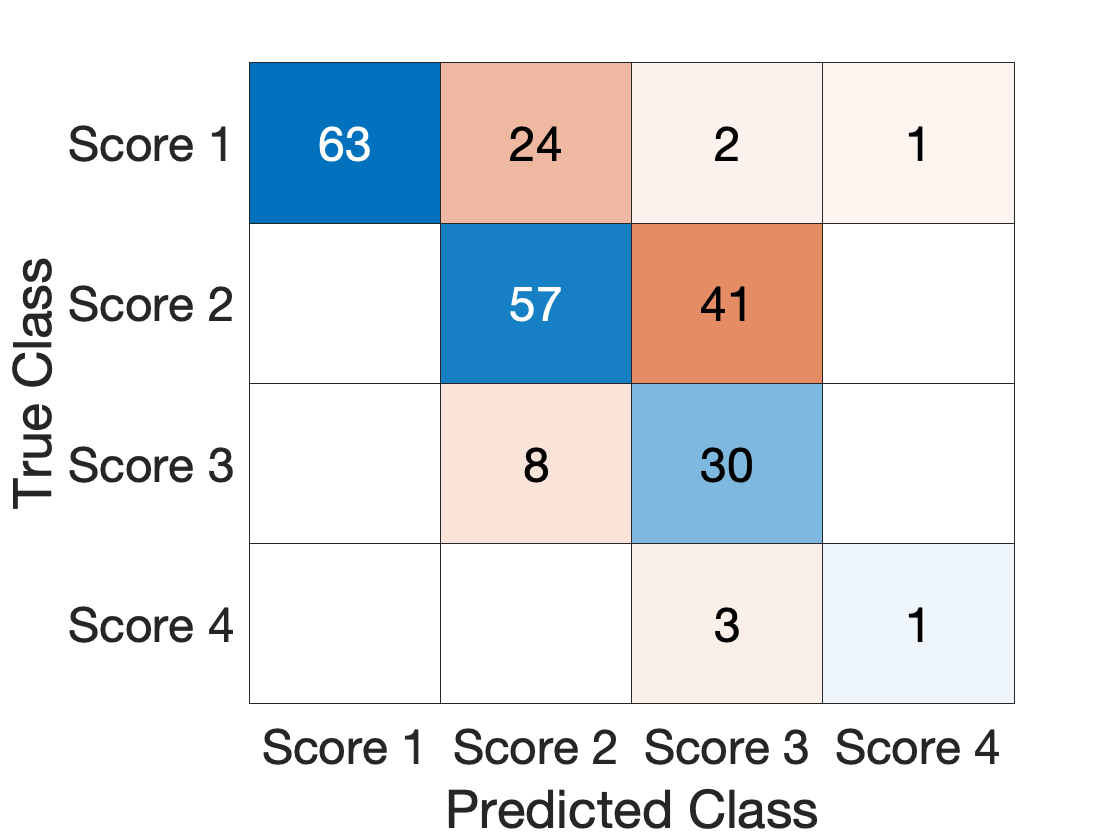

% Generate Confusion Matrix

YValidation = imdsValidation.Labels;
YTrue=imdsValidation.Labels;
figure;cm=confusionchart(YTrue,YPred);
set(gca,'FontSize',24)

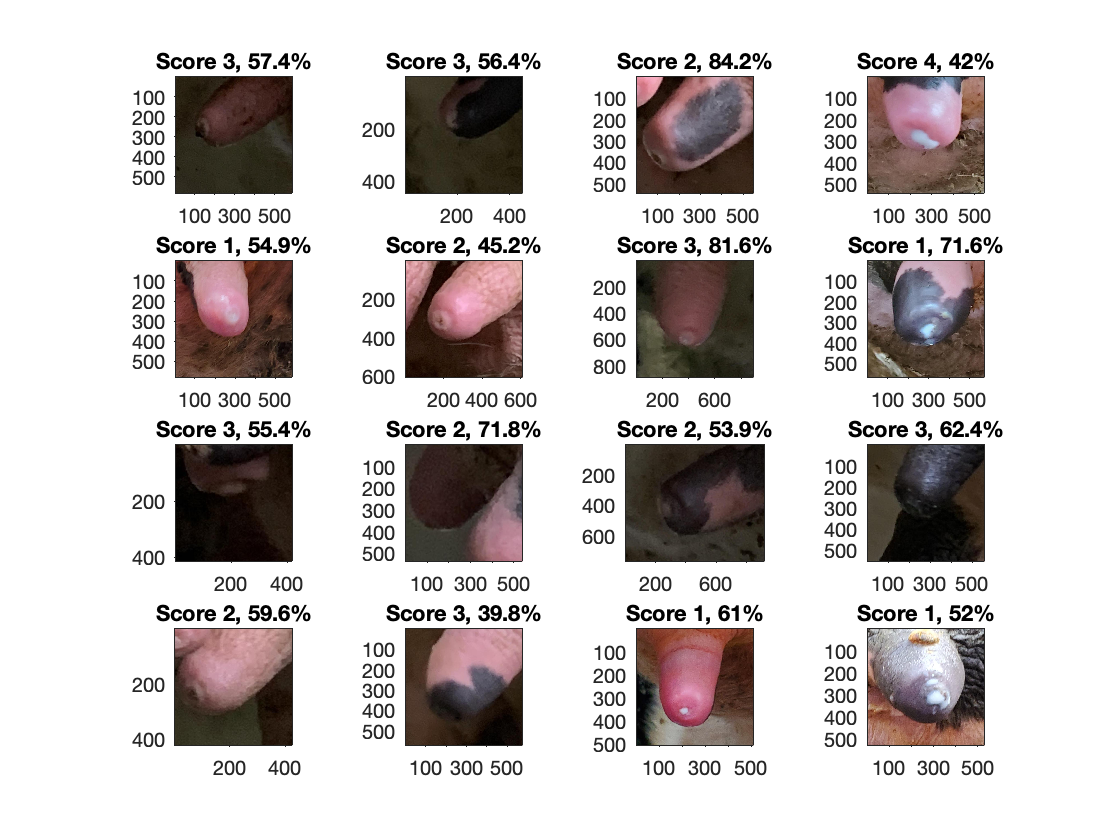

% Generate an image panel

N=16; % 4 x 4 array of images
idx = randperm(numel(imdsValidation.Files),N);
figure(1);clf
for i = 1:N
    subplot(sqrt(N),sqrt(N),i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

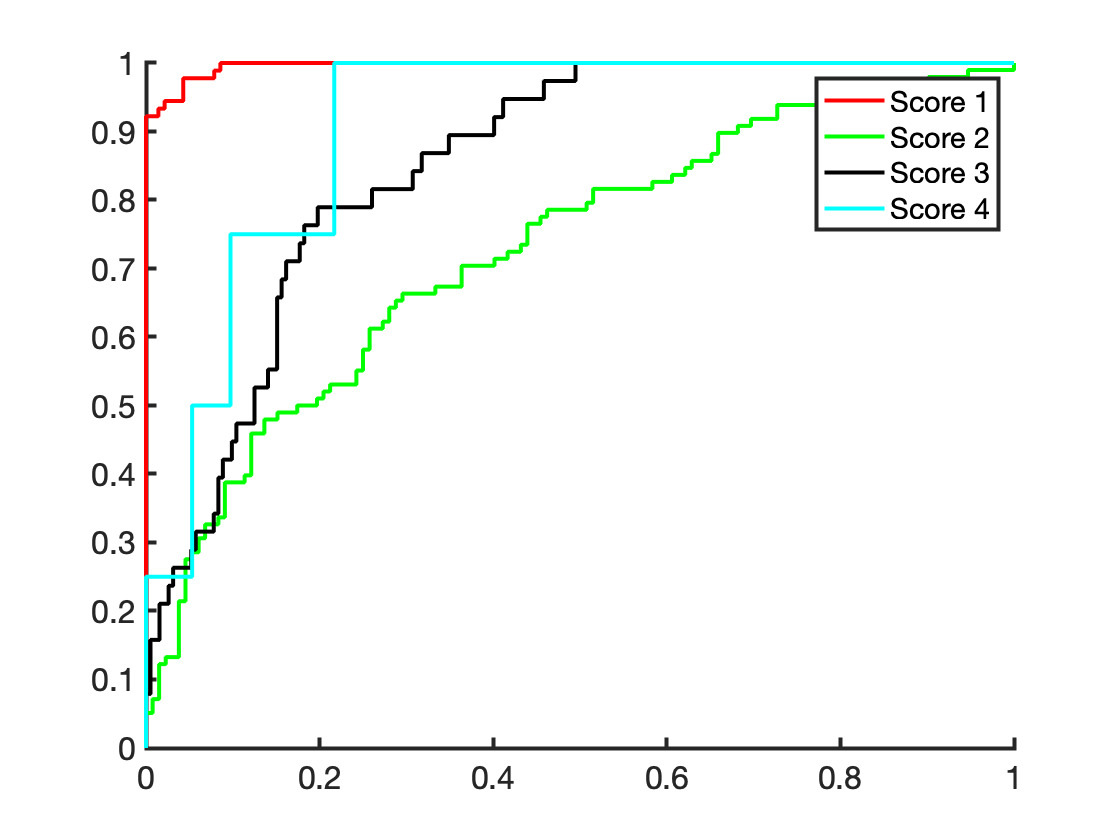

% Get AUC curves/values/errors. Note that the perfcurve label must
% correspond with the folder name. Here we have 4 folders labelled 'Score
% 1', 'Score 2', etc., 

[X1,Y1,T1,AUC1]=perfcurve(imdsValidation.Labels,probs(:,1),'Score 1');
[X2,Y2,T2,AUC2]=perfcurve(imdsValidation.Labels,probs(:,2),'Score 2');
[X3,Y3,T3,AUC3]=perfcurve(imdsValidation.Labels,probs(:,3),'Score 3');
[X4,Y4,T4,AUC4]=perfcurve(imdsValidation.Labels,probs(:,4),'Score 4');
%[XN,YN,TN,AUCN]=perfcurve(imdsValidation.Labels,probs(:,5),'ClassN');
figure(2);clf;hold on;
plot(X1,Y1,'r','LineWidth',2);
plot(X2,Y2,'g','LineWidth',2);
plot(X3,Y3,'k','LineWidth',2);
plot(X4,Y4,'c','LineWidth',2);
%plot(XN,YN,'k--','LineWidth',2);

set(gca,'linewidth',2);
set(gca,'FontSize',16);
legend('Score 1', 'Score 2', 'Score 3', 'Score 4');%, 'Class N');

% Display the AUC values 
[AUC1, AUC2, AUC3, AUC4]

ans =     0.9963    0.7274    0.8521    0.9082


## 9. FINAL TESTING... DO ONLY ONCE!

Uncomment this out if you want to run the script in its entirety.

% augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);
% [YPredTEST,probsTEST] = classify(net,augimdsTest);
% 
% [X1,Y1,T1,AUC1T]=perfcurve(imdsTest.Labels,probsTEST(:,1),'Class1');
% [X2,Y2,T2,AUC2T]=perfcurve(imdsTest.Labels,probsTEST(:,2),'Class2');
% [X3,Y3,T3,AUC3T]=perfcurve(imdsTest.Labels,probsTEST(:,3),'Class3');
% [X4,Y4,T4,AUC4T]=perfcurve(imdsTest.Labels,probsTEST(:,4),'Class4');
% %[XN,YN,TN,AUCN]=perfcurve(imdsTest.Labels,probsTEST(:,5),'ClassN');
% figure(2);clf;hold on;
% plot(X1,Y1,'r','LineWidth',2);
% plot(X2,Y2,'g','LineWidth',2);
% plot(X3,Y3,'k.-','LineWidth',2);
% plot(X4,Y4,'c','LineWidth',2);
% 
% set(gca,'linewidth',2);
% set(gca,'FontSize',16);
% legend('Class 1', 'Class 2', 'Class 3', 'Class 4');
% [AUC1T AUC2T AUC3T AUC4T]
% accuracyT = mean(YPredTEST == imdsTest.Labels)
% figure; C=confusionmat(imdsTest.Labels, YPredTEST);
% confusionchart(C);
% set(gca,'FontSize',24)

## Supporting function

This sub-function randomly replicate the image directry for each class. When the target class is A, the image directry of image A was found from imds.Files and the image directry was copied in order to balance the number of images over the classes. 

function files = randReplicateFiles(files,numDesired)
n = numel(files);
ind = randi(n,numDesired,1);
files = files(ind);
end